# Homework 13

## ADSI Problem 7.1

A tremendous amount of functionality is found in MATLABs toolboxes and Hilbert transforms are no exception. Type doc hilbert in MATLAB and read the documentation.  

doc hilbert

## ADSI Problem 7.2: Hilbert transform of a cosine signal

A continuous time signal is given by $x\left(t\right)=4+3\mathrm{cos}\left(\omega t\right)$. What is the Hilbert transform of this signal?  

## ADSI Problem 7.3: Analytical signals

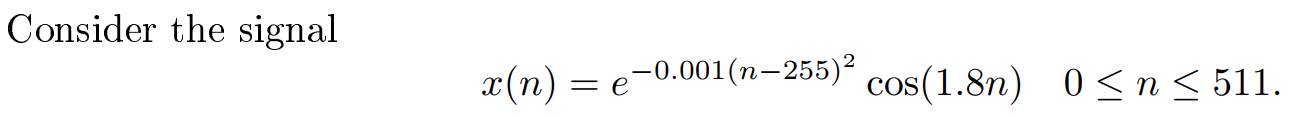

Calculate the analytical signal in MATLAB and check that the spectrum is one-sided as expected.  

To show that the spectrum is one-sided, we have to show that the $X_c \left(e^{j\omega } \right)$ is zero over the negative frequency range. When 

n = [0:511]';
x = exp(-0.001.*(n-225).^2).*cos(1.8*n);
plot(n,x)
xlim([0,511])
y = hilbert(x);
periodogram(y)

## ADSI Problem 7.4: Swept sine wave

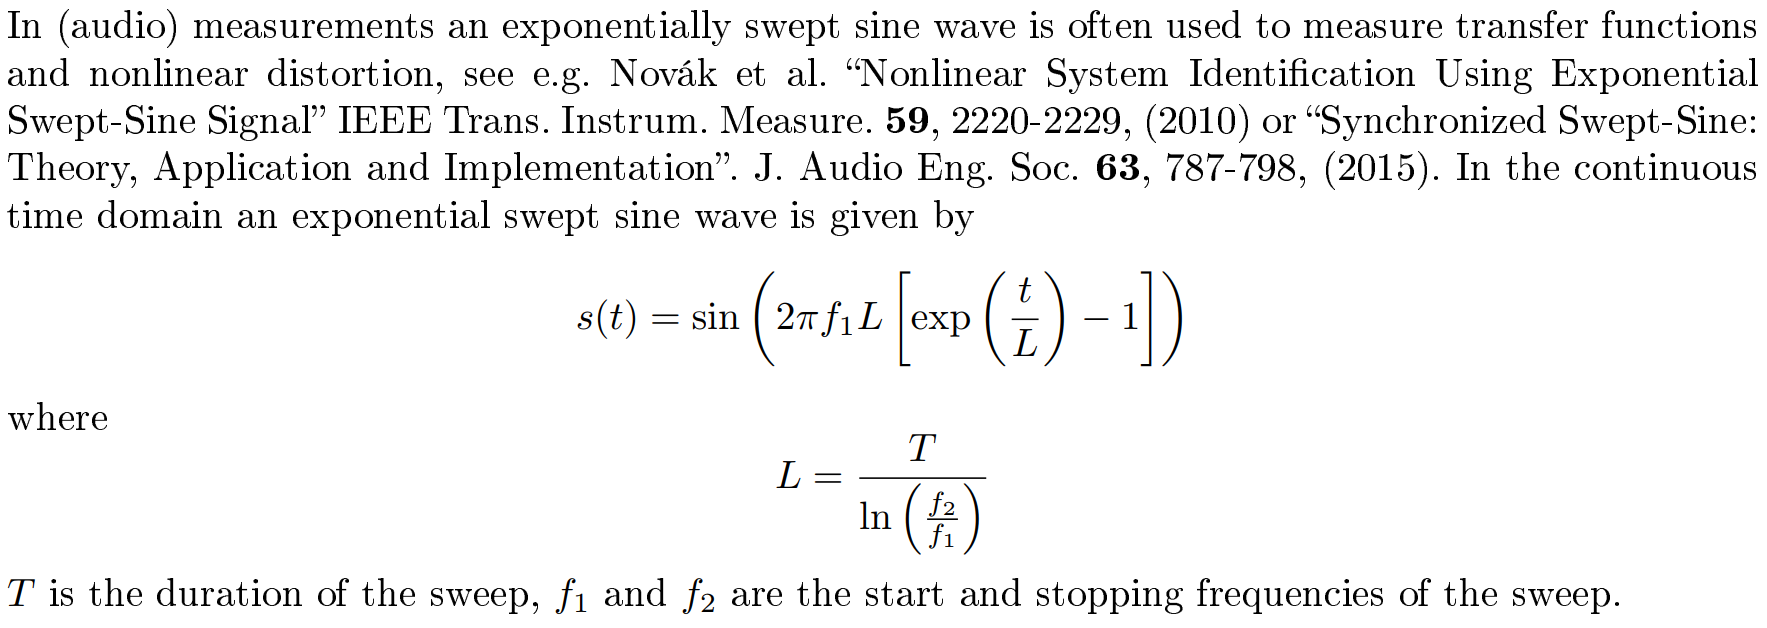

1. 

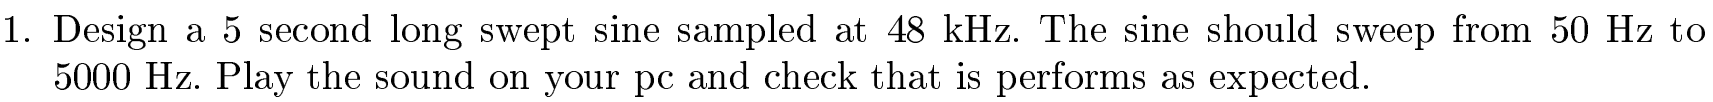

2. 

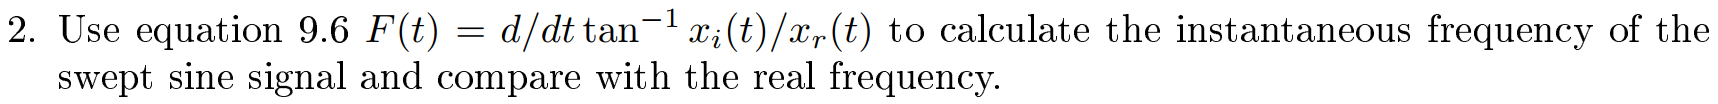

## ADSI Problem 7.5: Envelope Detection

The textbook states that the Hilbert transform can be used to find the envelope of a signal. The validity of this statement is investigated in this problem. 

Consider an exponentially decaying oscillating signal given by

        
$$x\left(n\right)=4e^{-0\ldotp 01n} \mathrm{cos}\left(\pi n\right)$$


### 1. Plot the signal and envelope on the same graph

Plot this signal and use equation 9.4 to plot the envelope on the same graph. Compare the result with the expected outcome.

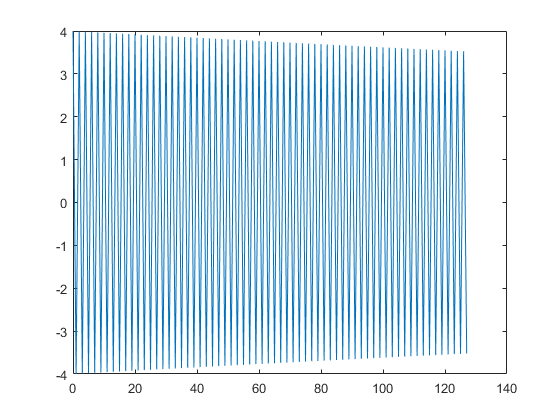

n = [0:127]';
x = 4*exp(-0.001.*n).*cos(pi*n);
plot(n, x)

### 2. Describe how noise affects Hilbert transform's ability to recover the envelope

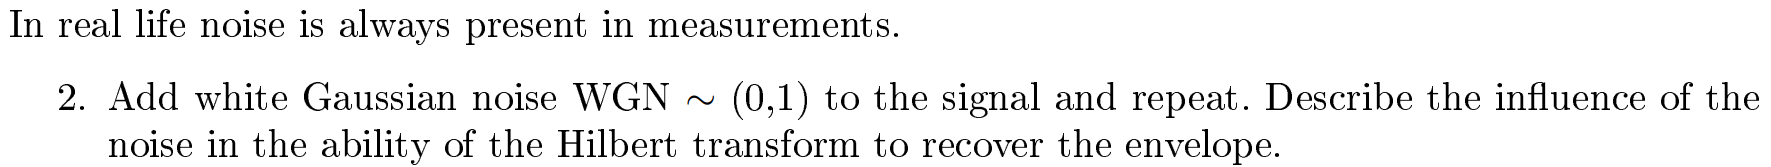

### 3. Try with other two signals

## ADSI Problem 7.8: Amplitude modulated signal

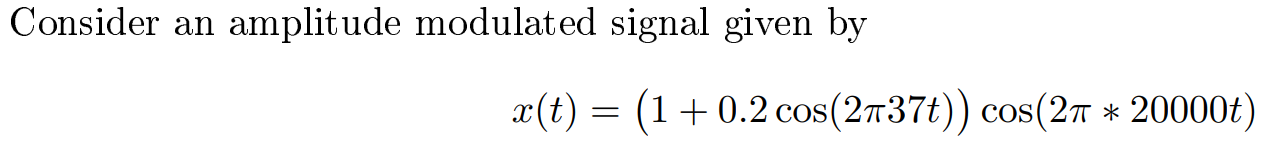

### 1. Plot 1 second of the signal and confirm that it is an amplitude modulated signal with a carrier frequency of 20 kHz.  

### 2. Use the procedure from Figure 9.8 in the note to frequency shift the signal to 15 kHz. Plot the spectrum of the signal at each step in the procedure.  